load('x_feat_utile_big.mat');
load('xLabelsMorph_verbose.mat');

utileNormResulst = normalize(x_feat_utile(:,1:50));





utileResulst = utileNormResulst(:,all(~isnan(utileNormResulst)));

%[rho, pval] = corr(x_feat_utile(:,1:50), 'type', 'Pearson');
[rho, pval] = corr(x_feat_utile(:,1:50), 'type', 'Spearman');
%rho = cov(x_feat_utile)
%rho(find(rho(:,:)>[0.7]))
size(rho)

ans =     50    50


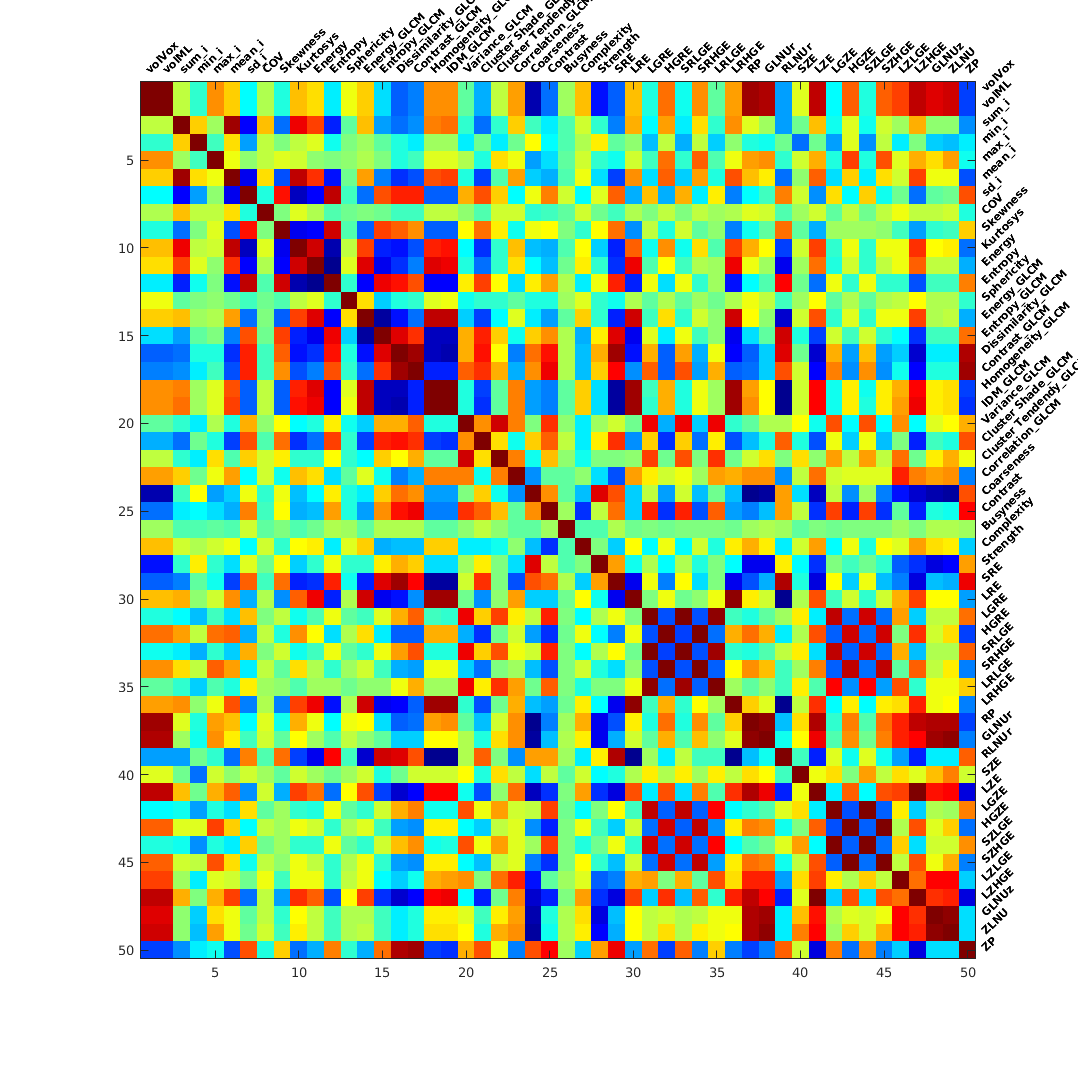


rhored = rho;

rhored(~any(~isnan(rhored), 2),:)=[];
rhored(:,~any(~isnan(rhored), 1))=[];

cuttedlabels = xLabelsMorph;

cuttedlabels(:,~any(~isnan(rho), 1))=[];


figure('Position',[0,0,1500,1500]);

image(rhored,'CDataMapping','scaled');
colormap('jet')
for i=1:size(rhored, 1)
    str = sprintf(cuttedlabels{i});
    ht = text(size(rhored,1) + 1, i, str, 'FontSize', 8, 'FontWeight', 'Bold', 'Interpreter', 'None');
    set(ht,'Rotation',45)
end

for i=1:size(rhored, 1)
    str = sprintf(cuttedlabels{i});
    ht = text(i, 0, str, 'FontSize', 8, 'FontWeight', 'Bold', 'Interpreter', 'None');
    set(ht,'Rotation',45)
end



load('x_feat_utile_big.mat');
load('xLabelsMorph_verbose.mat');

utileNormResulst = normalize(x_feat_utile(:,1:50));





utileResulst = utileNormResulst(:,all(~isnan(utileNormResulst)));

%[rho, pval] = corr(x_feat_utile(:,1:170));
%[rho, pval] = corr(x_feat_utile(:,1:170), 'type', 'Pearson');
[rho, pval] = corr(x_feat_utile(:,1:170), 'type', 'Spearman');
%rho = cov(x_feat_utile)
%rho(find(rho(:,:)>[0.7]))
size(rho)

ans =    170   170


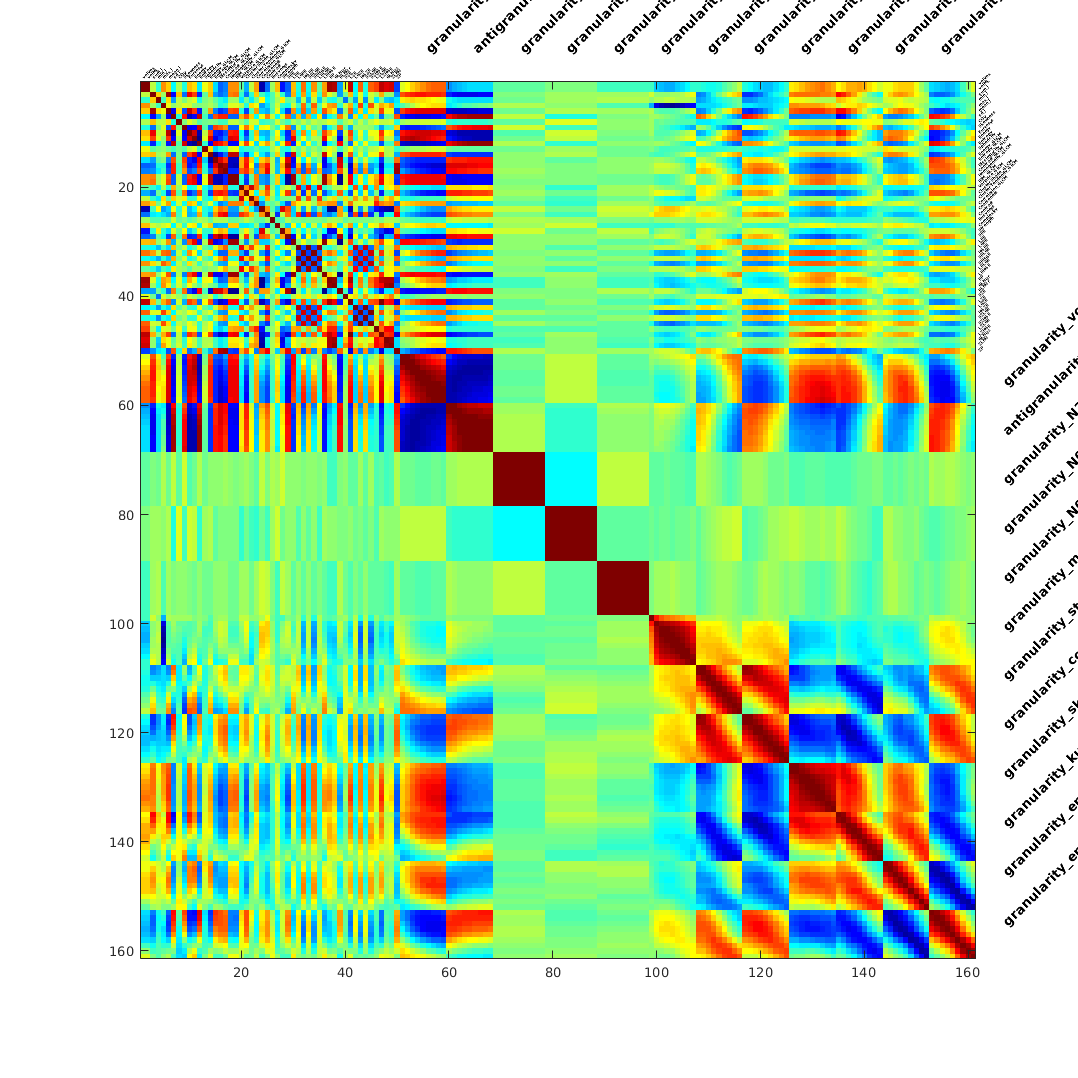


rhored = rho;

rhored(~any(~isnan(rhored), 2),:)=[];
rhored(:,~any(~isnan(rhored), 1))=[];

cuttedlabels = xLabelsMorph;

cuttedlabels(:,~any(~isnan(rho), 1))=[];


figure('Position',[0,0,1500,1500]);

image(rhored,'CDataMapping','scaled');
colormap('jet')
for i=1:50
    str = sprintf(cuttedlabels{i});
    ht = text(size(rhored,1) + 1, i, str, 'FontSize', 3, 'FontWeight', 'Bold', 'Interpreter', 'None');
    set(ht,'Rotation',45)
end

for i=1:50
    str = sprintf(cuttedlabels{i});
    ht = text(i, 0, str, 'FontSize', 3, 'FontWeight', 'Bold', 'Interpreter', 'None');
    set(ht,'Rotation',45)
end

for j=7:18
    i= j*9 - 7;
    str = sprintf(cuttedlabels{i});
    ht = text(size(rhored,1) + 1 + 5, i, str, 'FontSize', 10, 'FontWeight', 'Bold', 'Interpreter', 'None');
    set(ht,'Rotation',45)
end

for j=7:18
    i = j*9 - 7;
    str = sprintf(cuttedlabels{i});
    ht = text(i, -5, str, 'FontSize', 10, 'FontWeight', 'Bold', 'Interpreter', 'None');
    set(ht,'Rotation',45)
end




load('x_feat_utile_big.mat');
%load('xLabelsMorph_verbose.mat');

utileNormResulst = normalize(x_feat_utile(:,1:50));





utileResulst = utileNormResulst(:,all(~isnan(utileNormResulst)));

%[rho, pval] = corr(x_feat_utile(:,1:170));
%[rho, pval] = corr(x_feat_utile, 'type', 'Pearson');
[rho, pval] = corr(x_feat_utile, 'type', 'Spearman');
%rho = cov(x_feat_utile)
%rho(find(rho(:,:)>[0.7]))
size(rho)

ans =         1600        1600


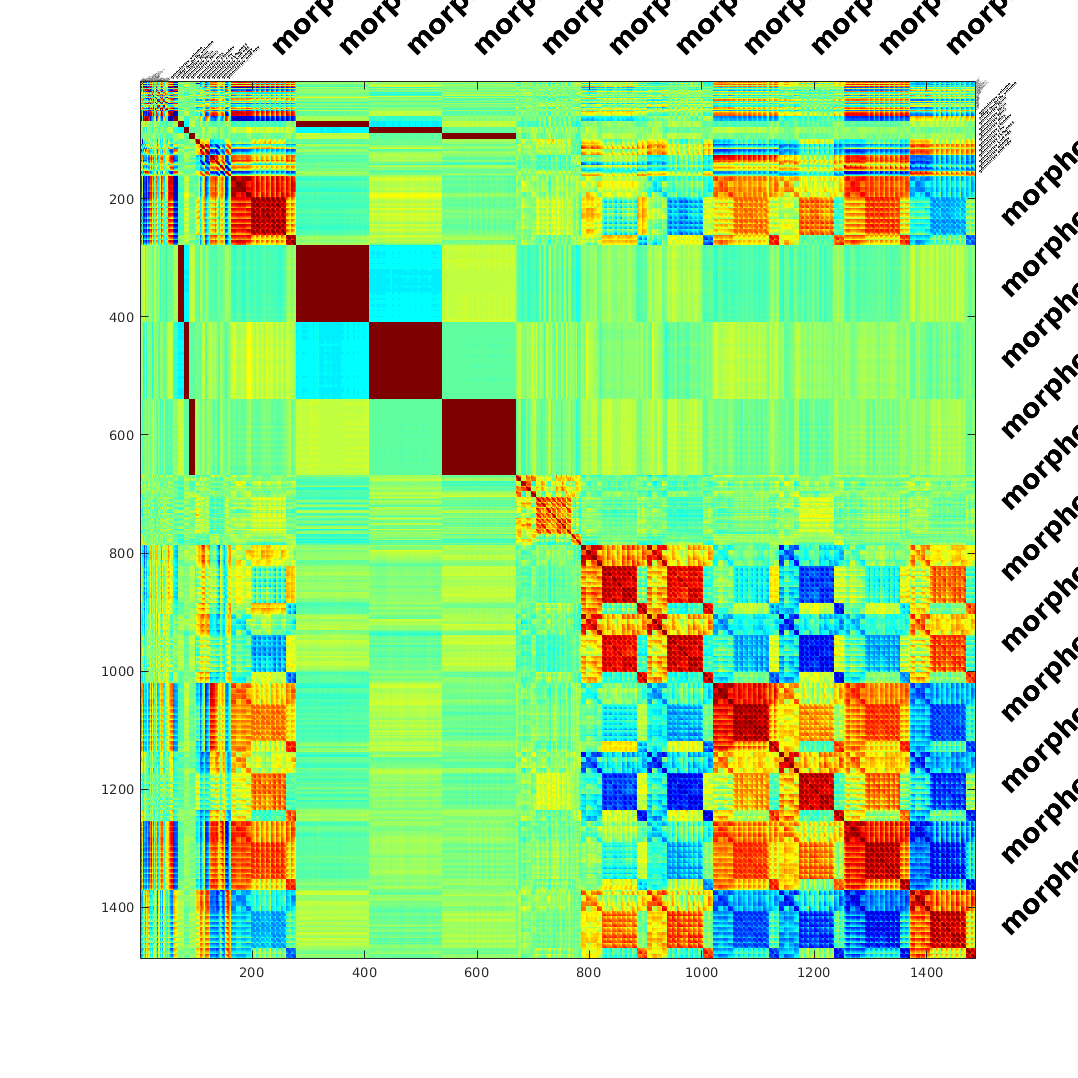


rhored = rho;

rhored(~any(~isnan(rhored), 2),:)=[];
rhored(:,~any(~isnan(rhored), 1))=[];


cuttedlabels = xLabelsMorph;

cuttedlabels(:,~any(~isnan(rho), 1))=[];


myfig3 = figure('Position',[0,0,1500,1500]);

image(rhored,'CDataMapping','scaled');
colormap('jet')
for i=1:50
    str = sprintf(cuttedlabels{i});
    ht = text(size(rhored,1) + 1, i, str, 'FontSize', 1, 'FontWeight', 'Bold', 'Interpreter', 'None');
    set(ht,'Rotation',45)
end

for i=1:50
    str = sprintf(cuttedlabels{i});
    ht = text(i, 0, str, 'FontSize', 1, 'FontWeight', 'Bold', 'Interpreter', 'None');
    set(ht,'Rotation',45)
end

for j=7:18
    i= j*9 - 7;
    str = sprintf(cuttedlabels{i});
    ht = text(size(rhored,1) + 1 + 5, i, str, 'FontSize', 3, 'FontWeight', 'Bold', 'Interpreter', 'None');
    set(ht,'Rotation',45)
end

for j=7:18
    i = j*9 - 7;
    str = sprintf(cuttedlabels{i});
    ht = text(i, -5, str, 'FontSize', 3, 'FontWeight', 'Bold', 'Interpreter', 'None');
    set(ht,'Rotation',45)
end


for j=2:12
    i= j*10*12 ;%- 5*6;
    str = sprintf(cuttedlabels{i});
    ht = text(size(rhored,1) + 1 + 50, i, str, 'FontSize', 20, 'FontWeight', 'Bold', 'Interpreter', 'None');
    set(ht,'Rotation',45)
end

for j=2:12
    i = j*10*12 ;%- 5*6;
    str = sprintf(cuttedlabels{i});
    ht = text(i, -50, str, 'FontSize', 20, 'FontWeight', 'Bold', 'Interpreter', 'None');
    set(ht,'Rotation',45)
end



%saveas(myfig3, '../mytest.eps', '-depsc2', 'painters', 'loose')






%%%%WITH DATANUM


load('x_feat_utile_big.mat');
load('xLabelsMorph_verbose.mat');

utileNormResulst = normalize(data_num(:,1:50));





utileResulst = utileNormResulst(:,all(~isnan(utileNormResulst)));

[rho, pval] = corr(data_num(:,2:53), 'type', 'Pearson');
%[rho, pval] = corr(data_num(:,2:53), 'type', 'Spearman');
%rho = cov(x_feat_utile)
%rho(find(rho(:,:)>[0.7]))
size(rho)

ans =     52    52


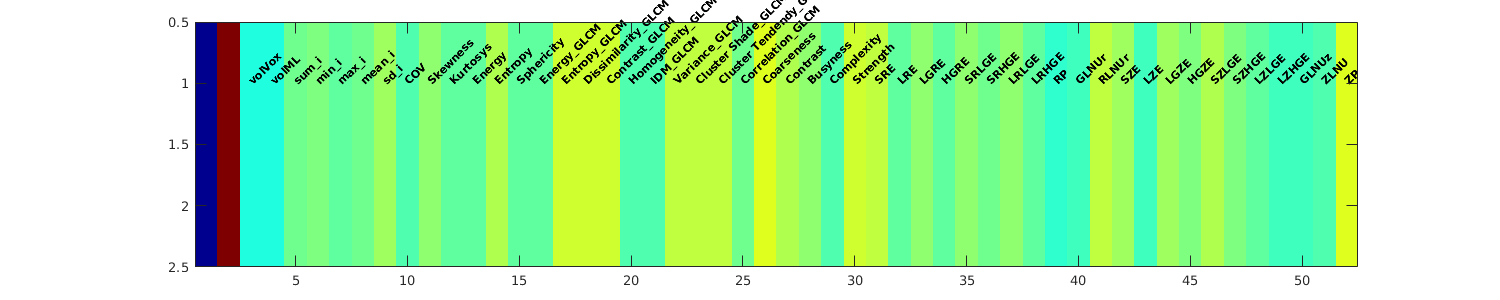


rhored = rho;

rhored(~any(~isnan(rhored), 2),:)=[];
rhored(:,~any(~isnan(rhored), 1))=[];

cuttedlabels = xLabelsMorph;

cuttedlabels(:,~any(~isnan(rho), 1))=[];



figure('Position',[0,0,1500,300]);
rhored = rhored(1:2,:);
rhored(:,1) = -rhored(:,1);
image(rhored,'CDataMapping','scaled');
colormap('jet')

for i=1:size(rhored, 2) - 2
    str = sprintf(cuttedlabels{i});
    ht = text(i+2, 1, str, 'FontSize', 8, 'FontWeight', 'Bold', 'Interpreter', 'None');
    set(ht,'Rotation',45)
end




load('x_feat_utile_big.mat');
load('xLabelsMorph_verbose.mat');

utileNormResulst = normalize(x_feat_utile(:,1:50));





utileResulst = utileNormResulst(:,all(~isnan(utileNormResulst)));

%[rho, pval] = corr(x_feat_utile(:,1:170));
%[rho, pval] = corr(x_feat_utile(:,1:170), 'type', 'Pearson');
[rho, pval] = corr(data_num(:,1:170), 'type', 'Spearman');
%rho = cov(x_feat_utile)
%rho(find(rho(:,:)>[0.7]))
size(rho)

rhored = rho;

rhored(~any(~isnan(rhored), 2),:)=[];
rhored(:,~any(~isnan(rhored), 1))=[];

cuttedlabels = xLabelsMorph;

cuttedlabels(:,~any(~isnan(rho), 1))=[];


figure('Position',[0,0,1500,1500]);

image(rhored,'CDataMapping','scaled');
colormap('jet')
for i=1:50
    str = sprintf(cuttedlabels{i});
    ht = text(size(rhored,1) + 1, i, str, 'FontSize', 3, 'FontWeight', 'Bold', 'Interpreter', 'None');
    set(ht,'Rotation',45)
end

for i=1:50
    str = sprintf(cuttedlabels{i});
    ht = text(i, 0, str, 'FontSize', 3, 'FontWeight', 'Bold', 'Interpreter', 'None');
    set(ht,'Rotation',45)
end

for j=7:18
    i= j*9 - 7;
    str = sprintf(cuttedlabels{i});
    ht = text(size(rhored,1) + 1 + 5, i, str, 'FontSize', 10, 'FontWeight', 'Bold', 'Interpreter', 'None');
    set(ht,'Rotation',45)
end

for j=7:18
    i = j*9 - 7;
    str = sprintf(cuttedlabels{i});
    ht = text(i, -5, str, 'FontSize', 10, 'FontWeight', 'Bold', 'Interpreter', 'None');
    set(ht,'Rotation',45)
end








% rhoreduced = rho(all(~isnan(rho(1,:)1)),:);
% rhoreduced = rhoreduced(:,all(~isnan(rho)));
% inds = find(rho(:)<[0.8]);
% inds2 = find(rho(:)>[-0.8]); 
% rho2 = rho;
% rho3 = rho;
% rho2(inds) = 0;
% rho3(inds2) = 0;
% rho2 = rho2 + rho3;




%myrowcols, myfucking = ind2sub([210, 210], find(rho(:)>[0.9]));